%Author:Juber Rahman
%course: Scientific Computing
%Homework 1:problem 2

% read images
disp('original images')

original images


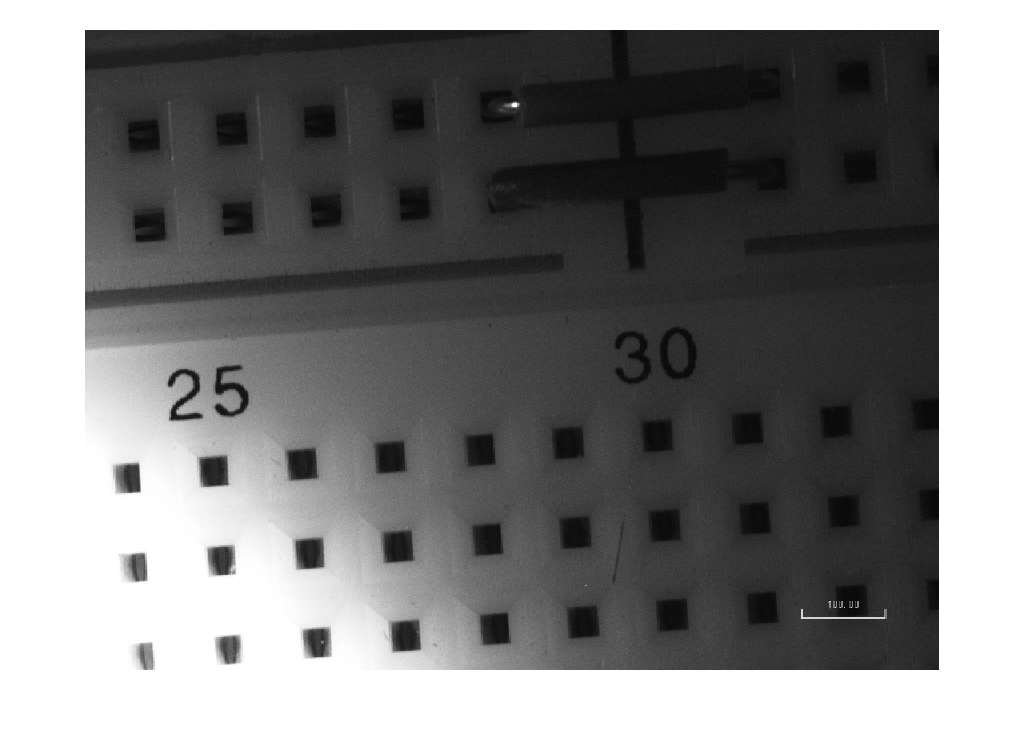

f1rgb=imread('Image1.jpg');
imshow(f1rgb)

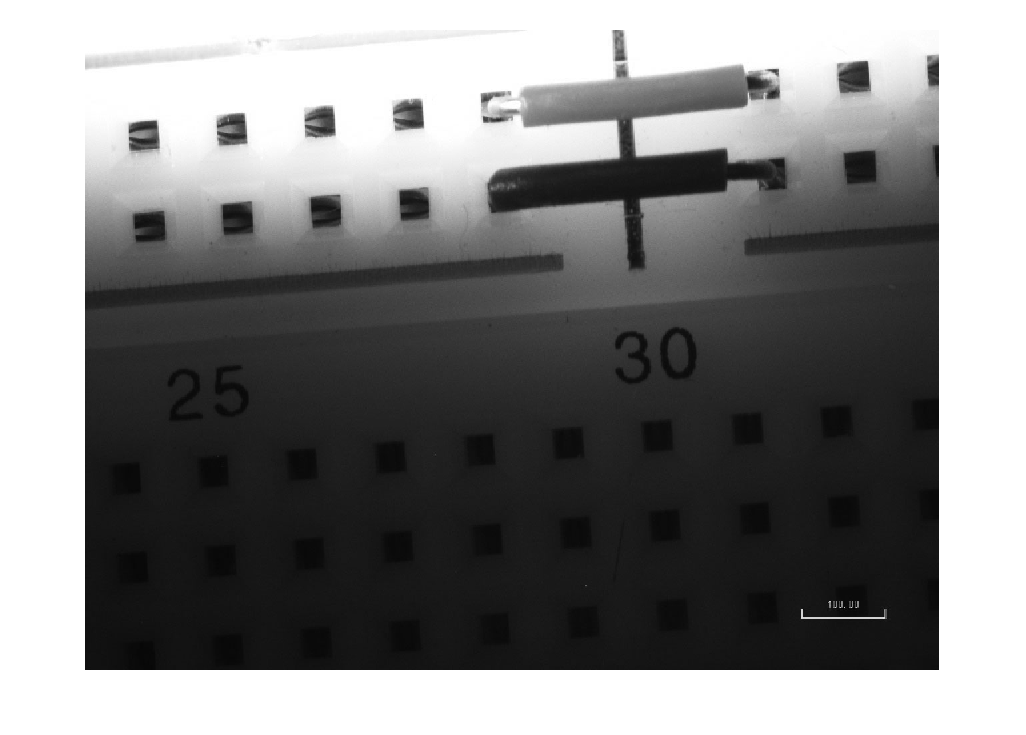

f2rgb=imread('Image2.jpg');
imshow(f2rgb)

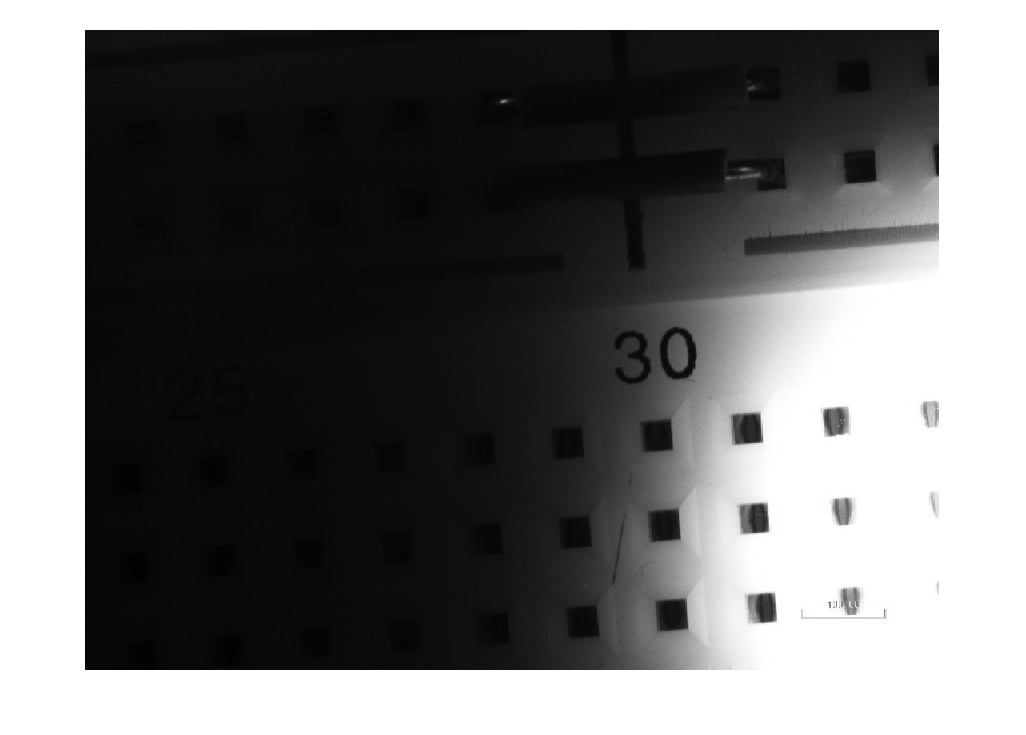

f3rgb=imread('Image3.jpg');
imshow(f3rgb)

% convert to vectors
f1=f1rgb(:);
f2=f2rgb(:);
f3=f3rgb(:);

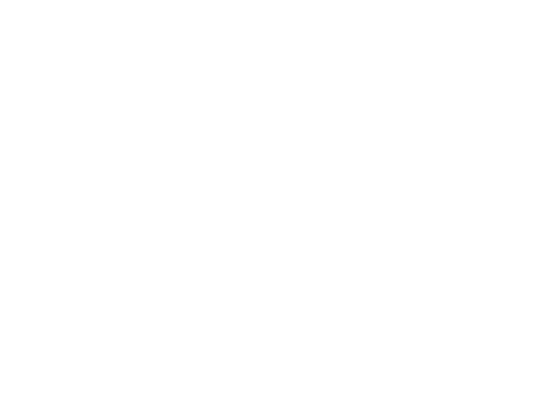

% form matix
M=horzcat(f1,f2,f3);
figure
imshow(M, 'InitialMagnification', 'fit')

K = mat2gray(M);

% do reduced singular value decomposition
[V,D]=eig(K'*K);
% calculate sigma
sigma=sqrt((eig(K'*K)));
% calculate U
for i=1:3
W(:,i)=V(:,i)/sigma(i);
end
U=K*W;
% show left singular vectors are orthogonal
for i=1:2
value=sum(U(:,i).*U(:,i+1))%sum of product of eigen vectors
end

value = 6.4115e-15

value = -2.4258e-14

sumProduct=round(value,3)

sumProduct = 0

if(sumProduct==0)
    disp("Left singular vector is orthogonal")
else 
    disp("Left singular vector is not orthogonal")
end 

Left singular vector is orthogonal


% left singular vectors in U span the images
% to span the images the vectors in U should be linearly independent
if rank(U)==3
    disp('linearly independent')
else 
    disp('not linearly independent')
end

linearly independent



% calculate alpha
alpha1N=(K(:,1)'*U(:,1));
alpha1D=(U(:,1)'*U(:,1));
alpha1=alpha1N/alpha1D;
% reconstruct image matrix
R(:,1)=350*U(:,1);
R(:,2)=10*U(:,2);
R(:,3)=20*U(:,3);
Rsum=sum(R,2);
Rmatrix1=reshape(Rsum,[],1280);
% show image 1
disp('Reconstructed images')

Reconstructed images


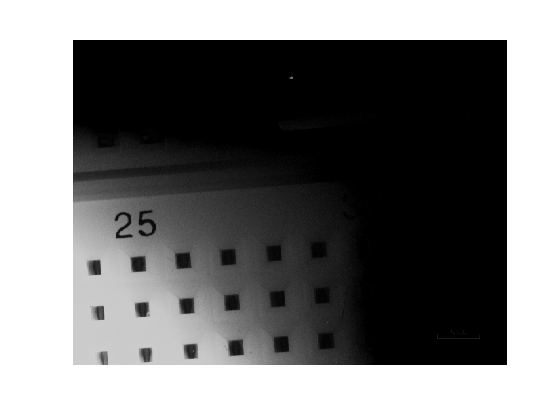

figure;
imshow(Rmatrix1, 'InitialMagnification', 'fit')

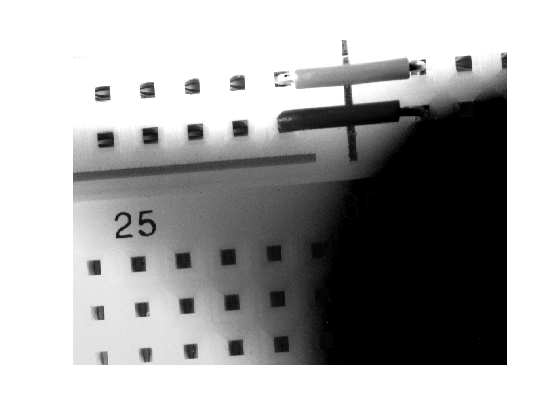

% reconstruct image matrix
R(:,1)=350*U(:,1);
R(:,2)=1000*U(:,2);
R(:,3)=200*U(:,3);
Rsum=sum(R,2);
Rmatrix2=reshape(Rsum,[],1280);
% show image 1
figure;
imshow(Rmatrix2, 'InitialMagnification', 'fit')

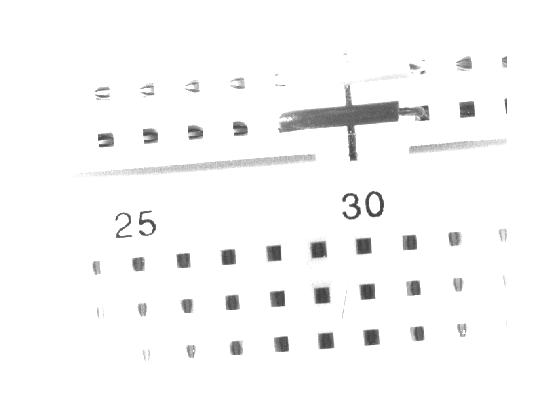

% reconstruct image matrix
R(:,1)=350*U(:,1);
R(:,2)=150*U(:,2);
R(:,3)=2000*U(:,3);
Rsum=sum(R,2);
Rmatrix3=reshape(Rsum,[],1280);
% show image 1
figure;
imshow(Rmatrix3, 'InitialMagnification', 'fit')

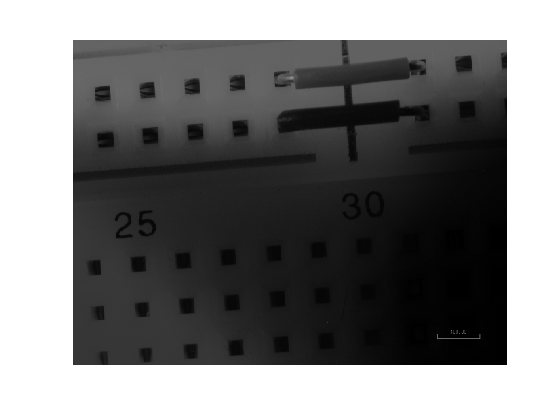

% reconstruct image matrix
R(:,1)=10*U(:,1);
R(:,2)=100*U(:,2);
R(:,3)=200*U(:,3);
Rsum=sum(R,2);
Rmatrix4=reshape(Rsum,[],1280);
% show image 1
figure;
imshow(Rmatrix4, 'InitialMagnification', 'fit')

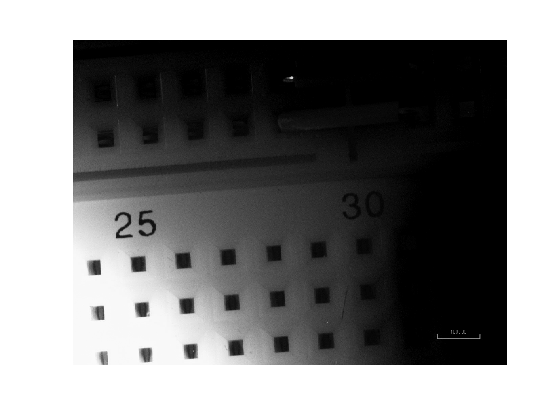

% reconstruct image matrix
R(:,1)=350*U(:,1);
R(:,2)=10*U(:,2);
R(:,3)=200*U(:,3);
Rsum=sum(R,2);
Rmatrix5=reshape(Rsum,[],1280);
% show image 1
figure;
imshow(Rmatrix5, 'InitialMagnification', 'fit')

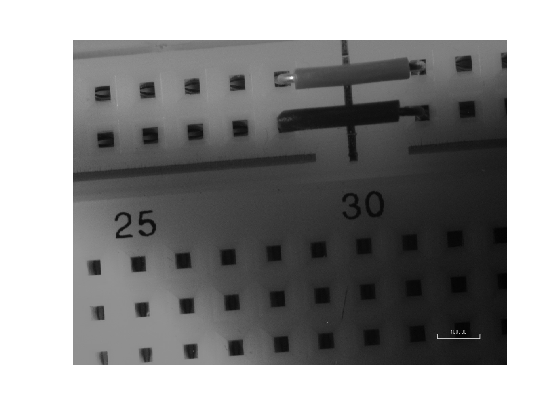

% reconstruct image matrix
R(:,1)=100*U(:,1);
R(:,2)=100*U(:,2);
R(:,3)=350*U(:,3);
Rsum=sum(R,2);
Rmatrix6=reshape(Rsum,[],1280);
% show image 1
figure;
imshow(Rmatrix6, 'InitialMagnification', 'fit')